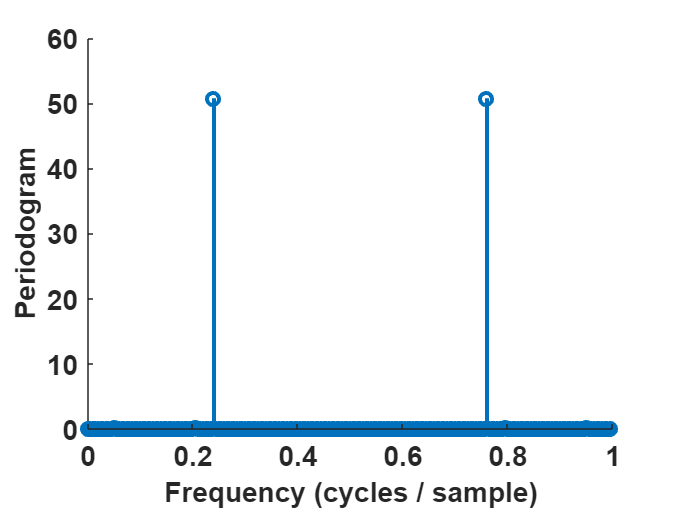

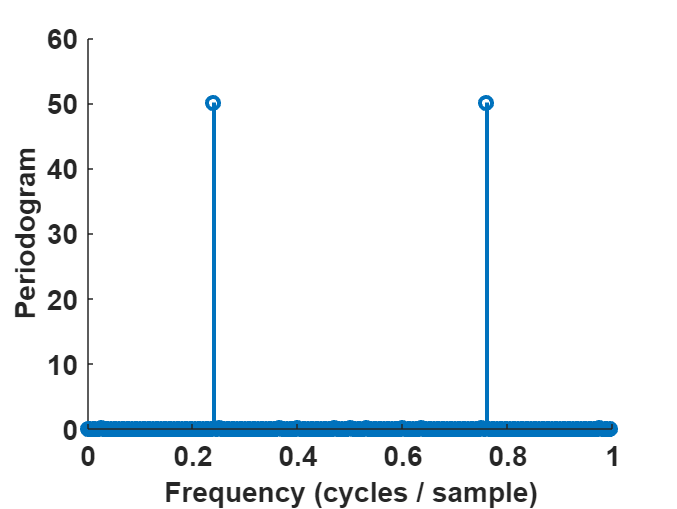

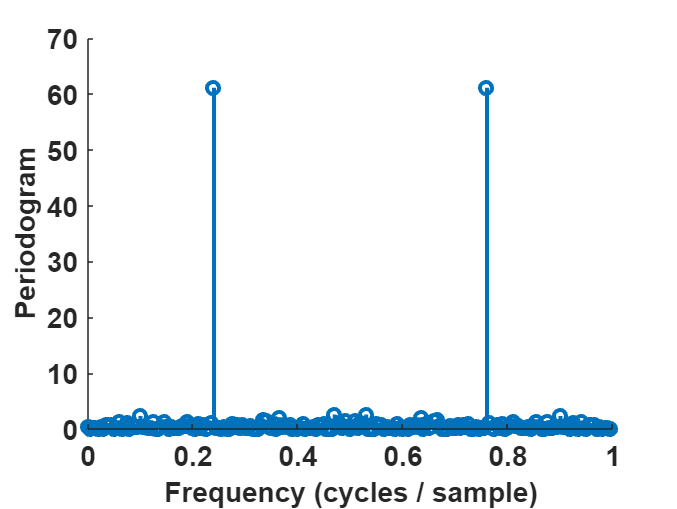

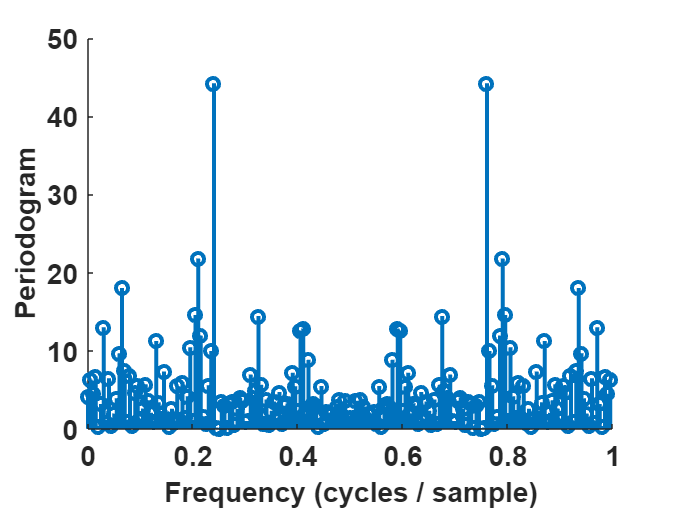

clc;
clear variables;

% Define parameters
A = 1;
f0 = 0.24;
N = 200;
SNR = [20, 10, 1, 0.1]; % Signal to noise ratios

% Generate the signal
t = (0:N-1)'; % Time vector
y = A*sin(2*pi*f0*t); % Signal


for i = 1:length(SNR)
 sigma_e = sqrt(var(y)/((SNR(i)))); % Adjust sigma_e based on SNR
 e = sigma_e*randn(N,1); % Generate noise
 y_noisy = y + e; % Add noise to the signal
 % Compute periodogram
 Y = fft(y_noisy);
 fvec = (0:N-1)'/N; 
 P = abs(Y).^2/N;
 % Plot periodogram
 figure
 stem(fvec,P,'LineWidth',2)
 set(gca,'fontsize',14,'fontweight','bold');
 box off
 xlabel('Frequency (cycles / sample)','FontSize',14,'FontWeight','bold')
 ylabel('Periodogram','FontSize',14,'FontWeight','bold')
end